# **Orbital Mechanics Project: Free-Return Trajectory for Earth-Moon Mission**

Code Initiation:

clc
clear
close all
format long

set(0,'DefaultFigureWindowStyle','normal')

## Optimal Parking Orbit Altitude

For Hohmann Transfer between two circular orbits (from earth to parking orbit)

syms dVt dVp dVa ra z e
re = 6378;  % km
mu = 3.986e5;
ra = re + z

$$ra = z+6378$$

e = (ra - re)/(ra + re)

$$e = \frac{z}{z+12756}$$

dVp = sqrt(mu/re)*(sqrt(1 + e) - 1);
dVa = sqrt(mu/ra)*(1 - sqrt(1 - e));
f1 = dVt == abs(dVp) + abs(dVa);
dVt = rhs(f1);
derdVt = diff(dVt, z)

$$derdVt = \begin{array}{l} \frac{5\,\sqrt{3986}\,\left(\frac{\sigma_{3}\,\left(\bar{\sigma_{2}}-1\right)}{2\,\sigma_{2}}-\frac{\left(\sigma_{2}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{2}}}\right)\,\sigma_{4}}{\sqrt{\left(\sigma_{2}-1\right)\,\left(\bar{\sigma_{2}}-1\right)}}-\frac{\frac{4450370593380899\,\sigma_{3}\,\sigma_{5}}{1125899906842624\,\sigma_{7}}-\frac{4450370593380899\,\sigma_{1}\,\sigma_{6}}{1125899906842624\,\bar{\sigma_{7}}}}{2\,\sqrt{\sigma_{5}\,\sigma_{6}}}-\frac{5\,\sqrt{3986}\,\left|\sigma_{2}-1\right|\,\left(z+\bar{z}+12756\right)}{2\,{\left|z+6378\right|}^{2}\,\sqrt{\left(\bar{z}+6378\right)\,\left(z+6378\right)}\,\sigma_{4}}\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{\bar{z}+12756}-\frac{\bar{z}}{{\left(\bar{z}+12756\right)}^{2}}\\ \sigma_{2}=\sqrt{1-\frac{z}{z+12756}}\\ \sigma_{3}=\frac{z}{{\left(z+12756\right)}^{2}}-\frac{1}{z+12756}\\ \sigma_{4}=\sqrt{\frac{1}{\left|z+6378\right|}}\\ \sigma_{5}=\frac{4450370593380899\,\bar{\sigma_{7}}}{562949953421312}-\frac{4450370593380899}{562949953421312}\\ \sigma_{6}=\frac{4450370593380899\,\sigma_{7}}{562949953421312}-\frac{4450370593380899}{562949953421312}\\ \sigma_{7}=\sqrt{\frac{z}{z+12756}+1} \end{array}$$

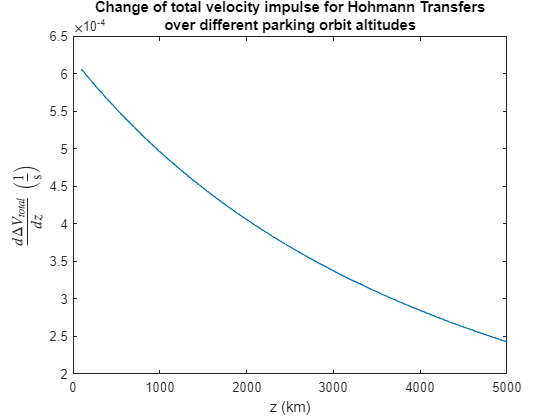

f2 = 0 == derdVt;
x = lhs(f2);
% y = subs(rhs(f2), mu, 3.986e5)
y = rhs(f2);
zs = 100:50:5000;
plot(zs, subs(y, z, zs))
title({'Change of total velocity impulse for Hohmann Transfers', 'over different parking orbit altitudes'})
xlabel('z (km)')
ylabel('$\frac{d\Delta V_{total}}{dz} \ \left(\frac{1}{\rm{s}}\right)$', Interpreter='latex')

% dVt = subs(dVt, mu, 3.986e5)
plot(zs, subs(dVt, z, zs))
% title({'Total Velocity Impulse required to perform Hohmann Transfer', 'for different parking orbit altitudes'})
xlabel('z')
ylabel('dVt')
hold on
syms dep 
dep = (mu/2)*( (1/re) - (1/ra) )

$$dep = \frac{99650}{3189}-\frac{199300}{z+6378}$$

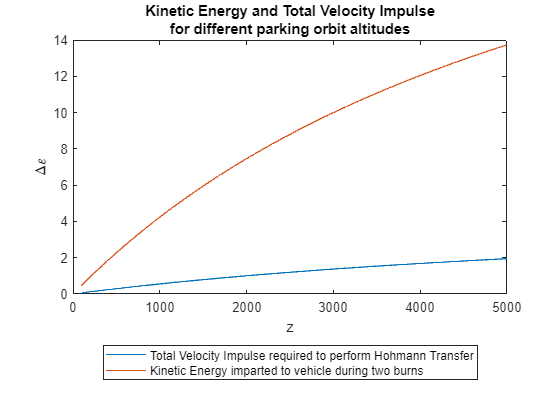

% dep = subs(dep, mu, 3.986e5)
plot(zs, subs(dep, z, zs))
title({'Kinetic Energy and Total Velocity Impulse', 'for different parking orbit altitudes'})
xlabel('z')
ylabel('$\Delta \varepsilon$', Interpreter='latex')
legend('Total Velocity Impulse required to perform Hohmann Transfer', 'Kinetic Energy imparted to vehicle during two burns', Location='southoutside')
hold off

Based on online sources, it is generally accepted that the optimal earth parking orbit is in LEO (Low Earth Orbit), which is between 160km - 2000km. Apollo 11 went into a nearly circular earth parking orbit of ~185.9 km. Since that mission was successful, a parking orbit altitude of **190km** will be used. It requires less total velocity impulse to obtain the orbit via Hohmann Transfer compared to higher LEOs, while still being high enough to avoid atmospheric drag.

## Parking Orbit, 3 hour system check, and preparation for TLI

For z = 190km, we can get $\Delta V_p$, $\Delta V_a$, and $\Delta V_{total}$

z_val = 190;    % km
dVp_val = double(subs(dVp, z, z_val));  dVa_val = double(subs(dVa, z, z_val));  dVt_val = dVp_val + dVa_val;
disp([dVp_val, dVa_val, dVt_val])

   0.057800238057830   0.057377600720562   0.115177838778392



po.r = re + z_val;
po.v = sqrt(mu/po.r);
a_transfer = (re + po.r)/2

a_transfer =         6473


Since c $\Delta V_p \approx \Delta V_a$, then at z = 190km, the velocity of our spacecraft is $V_e$. Since we needs a 3-hour system checkout in the parking orbit, we need to make sure that the spacecraft orbits for more than 3 hours

sys_check = 3;    % hours
po.T = 2*pi*sqrt((po.r^3)/mu)/ (60*60)  % hours

po = struct with fields:
    r: 6568
    v: 7.790262199699897
    T: 1.471493799982799


if (po.T > sys_check)
    disp('Proceed')
else
    disp('Spacecraft will orbit Earth more than once')
end

Spacecraft will orbit Earth more than once


sys_check/po.T

ans =    2.038744573735254


sys_check - (po.T * 2)

ans =    0.057012400034403


Assuming that the spacecraft launched at the left of the Earth ($0 ^o$ w.r.t. the earth-moon line) and the spacecraft reached parking orbit at the right of Earth ($180^o$ counterclockwise w.r.t. the earth-moon line), the spacecraft must stay in the parking orbit for at least 3 hours, orbiting 2 and a half times if we want to apply TLI at $0 ^o$ w.r.t. the earth-moon line.

T.hohmann = pi*sqrt((a_transfer^3)/mu) / (60*60);   % hours
T.sys = sys_check;
T.sys_to_tli = (po.T * 2.5) - sys_check

T = struct with fields:
       hohmann: 0.719841921782681
           sys: 3
    sys_to_tli: 0.678734499956997


## Transfer from Earth to Moon, Earth Centered Frame

Find eccentricity of transfer ellipse toward Lunar radius

m.r = 1749;  % km, radius of Moon
rp = po.r  % Perigee Radius of Transfer Ellipse

rp =         6568


rem = 384400; % Apogee Radius of Transfer Ellipse, which is approximately the distance from the earth to the moon
e_em = 1 - rp/rem;
a_em = rp / (1 - e_em);  % Semi-major axis of earth-moon transfer ellipse
m.soi = (0.073e24/5.97219e24)^(2/5)*(3.844e5)   % Radius of Sphere of Influence of Moon

m = struct with fields:
      r: 1749
    soi: 6.601750038582264e+04


**Figure 9.2 **from *Orbital Mechanics for Engineering Students, Fourth Edition* by Howard D. Curtis:

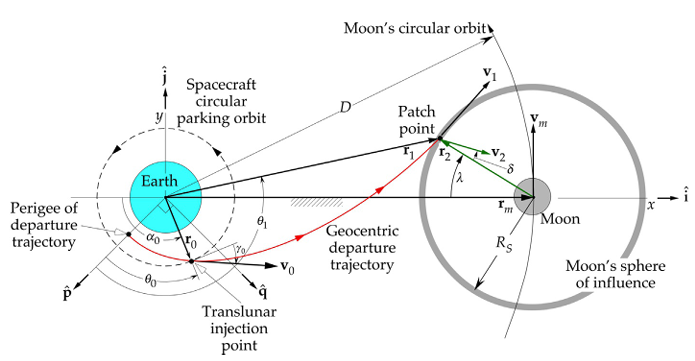

alpha = 0;      % Degrees
gamma = 0;      % Degrees
lam = 69;       % Degrees (guess value, preferable close to textbook examples and Lecture Notes 17 example)
r0 = [-rp*cosd(alpha) -rp*sind(alpha) 0]           % Position Vector of Translunar Injection

r0 =        -6568           0           0


r1 = [ rem - m.soi*cosd(lam) m.soi*sind(lam) 0]    % Position Vector of Patch Point

r1 = 1.0e+05 *

   3.607414437526267   0.616326461664755                   0


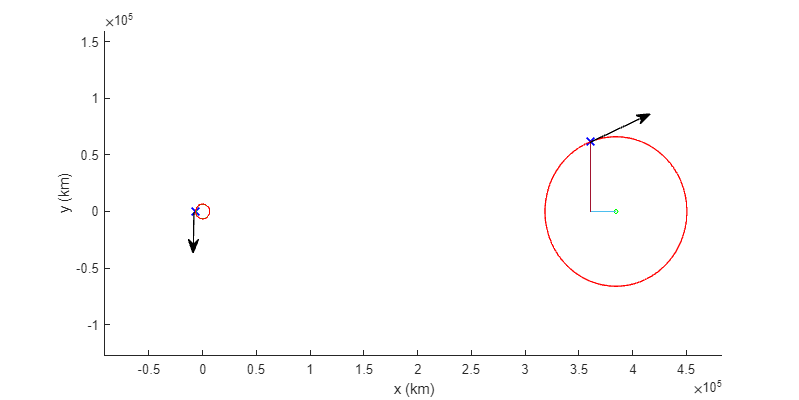

x = [r0(1) r1(1)];
y = [r0(2) r1(2)];
fig = figure(); 
fig.Position(3:4) = [1000, 500];
axis([(-1.0e4)*2 (5.0e5)*2 (-1.0e4) (5.0e5)]);
hold on
plot(x, y, Marker="x", MarkerSize=8, MarkerEdgeColor="b", LineWidth=1.5, LineStyle="none")

te = 0: 180.0 / 50.0: 2.0 * 180.0;

% plot Earth and Moon
plot(re*sind(te), re*cosd(te), 'Color', 'g');
plot(m.r*sind(te) + rem, m.r*cosd(te), 'Color', 'g');

% plot circular earth orbit
plot(rp * sind(te), rp * cosd(te), 'Color', 'r');

% plot Moon SOI
plot((m.soi * sind(te)) + rem, (m.soi * cosd(te)), 'Color', 'r');

plot([rem r1(1)], [0 0])
plot([r1(1) r1(1)], [0 r1(2)])
hold off

annotation("arrow", [0.7384 0.8135], [0.644 0.715])
annotation("arrow", [0.2428 0.2416], [0.469 0.3675])
xlim([-91787 483976])
ylim([-127609 160273])
xlabel('x (km)')
ylabel('y (km)')

% Unit vectors of position vectors r0 and r1
r0mag = norm(r0);
u0 = r0/r0mag;
r1mag = norm(r1);
u1 = r1/r1mag;

% Lagrange Coefficients

Sweep angle: 


$$\cos(\Delta \theta) = \bf{\hat{u}}_{\rm{r_0}} \cdot \bf{\hat{u}}_{\rm{r_1}} $$


sweep = acosd(dot(u0, u1))  % degrees

sweep =      1.703046324184772e+02


h1 = (sqrt(mu*r0mag))*(sqrt( (1 - cosd(sweep)) / ((r0mag/r1mag) + sind(sweep)*tand(gamma) - cosd(sweep)) ))

h1 =      7.196970712611065e+04


f = 1 - (mu*r1mag/(h1^2))*(1 - cosd(sweep))

f =  -54.924093141386493


g = (r0mag*r1mag/h1)*(sind(sweep))

g =      5.624633421282169e+03


g_dot = 1 - (mu*r0mag/(h1^2))*(1 - cosd(sweep))

g_dot =   -0.003663986231258


% Velocity vectors
v0 = (1/g)*(r1 - f.*r0)

v0 =    0.000000000000031  10.957628977787843                   0


v0mag = norm(v0)

v0mag =   10.957628977787843


vr0 = dot(v0, u0)

vr0 =     -3.104610908146896e-14


v1 = (1/g)*(g_dot.*r1 - r0)

v1 =    0.932727152883535  -0.040148601701853                   0


v1mag = norm(v1)

v1mag =    0.933590837543321


vr1 = dot(v1, u1)

vr1 =    0.912643680083138


dV0 = sqrt(po.v^2 + v0mag^2 - 2*po.v*v0mag*cosd(gamma)) % Delta V (TLI)

dV0 =    3.167366778087945


e1 = (1/mu)*((v0mag^2 - (mu/r0mag))*r0 - r0mag*vr0*v0); % Eccentricity vector of translunar trajectory

e1 =   -0.978468008850911   0.000000000000006                   0


e1mag = norm(e1)   % Eccentricity of translunar trajectory

e1mag =    0.978468008850911


Perifocal Unit Vectors

p1 = e1/e1mag

p1 =   -1.000000000000000   0.000000000000006                   0


w1 = cross(r1, v1)/h1

w1 =                    0                   0  -0.999999999999999


q1 = cross(w1, p1)

q1 =    0.000000000000006   0.999999999999999                   0


a1 = (h1^2/mu)*(1/(1 - (e1mag)^2)) % Semimajor axis of transfer ellipse

a1 =      3.050344928401090e+05


T1 = 2*pi*sqrt((a1^3)/mu)   % Period of TLJ in Seconds

T1 =      1.676620023006308e+06


theta0 = acosd(dot(p1, u0))

theta0 =      0


theta1 = theta0 + sweep

theta1 =      1.703046324184772e+02


Time of TLI and time of arrival at patch point:

Tterm = T1/(2*pi);
eterm = sqrt((1 - e1mag)/(1 + e1mag));
term0 = 2*atan(eterm*tand(theta0/2));
t0 = Tterm*( term0 - (e1mag*sin(term0)) );
term1 = 2*atan(eterm*tand(theta1/2));
t1 = Tterm*( term1 - (e1mag*sin(term1)) );
T.tli = t1 - t0

T = struct with fields:
       hohmann: 0.719841921782681
           sys: 3
    sys_to_tli: 0.678734499956997
           tli: 2.184209472894811e+05


Here, $\Delta t_1 = t_1 - t_0 = t_1$ because we applied TLI at $\alpha_o= 0^o$

## Moon-Centered Frame

Now we can treat this problem like a Lunar Flyby.

m.mu = 4.90487e3;  % Gravitational Parameter of Moon

The angular speed of the Moon w.r.t to the Earth can be estimated to be the tangential velocity for a rotating frame and assuming a circular orbit

m.V = [0 sqrt(mu/rem) 0]

m = struct with fields:
      r: 1749
    soi: 6.601750038582264e+04
     mu: 4.904870000000000e+03
      V: [0 1.018302846300942 0]


Velocity at arrival point relative to the Moon

r2 = [ -m.soi*cosd(lam) m.soi*sind(lam) 0]    % Position Vector of Lunar Arrival relative to Moon

r2 = 1.0e+04 *

  -2.365855624737333   6.163264616647548                   0


r2mag = norm(r2);
u2 = r2/r2mag;  % Unit Vector of r2
v2 = v1 - m.V

v2 =    0.932727152883535  -1.058451448002795                   0


v2mag = norm(v2)

v2mag =    1.410779716860658


vr2 = dot(v2, u2)

vr2 =   -1.322409071517128


h2 = cross(r2, v2)

h2 = 1.0e+04 *

                   0                   0  -3.244500946584715


h2mag = norm(h2)

h2mag =      3.244500946584715e+04


e2 = ((cross(v2, h2))/m.mu) - u2

e2 =    7.359872015828464   5.236275513488764                   0


e2mag = norm(e2)

e2mag =    9.032513345826672


Perilune Radius and Altitude

m.rp = ((h2mag^2)/m.mu)*(1/(1+ e2mag))

m = struct with fields:
      r: 1749
    soi: 6.601750038582264e+04
     mu: 4.904870000000000e+03
      V: [0 1.018302846300942 0]
     rp: 2.139235332970537e+04


m.z = m.rp - m.r;
disp("Perilune Altitude = " + m.z + " > 100km")

Perilune Altitude = 19643.3533 > 100km


Perifocal Unit Vector

p2 = (e2/e2mag)

p2 =    0.814819943690310   0.579714118652047                   0


True anomaly of patch point on lunar approach hyperbola, measured positive clockwise from perilune

theta2 = 360 - acosd(dot(p2, u2))

theta2 =      2.844304377804260e+02


Time relative to Perilune at patch point

one = (h2mag^3)/((m.mu^2)*(((e2mag^2) - 1)^(3/2)));
e2term = sqrt((e2mag - 1)/(e2mag + 1));
term2 = 2*atanh(e2term*tand(theta2/2));
t2 = one*( (e2mag*sinh(term2)) - 2*term2 )

t2 =     -4.069105014836327e+04


Since this is time *until* Perilune, the elapsed time from the Patch Point to Perilune is

T.perilune = 0 - t2

T = struct with fields:
       hohmann: 0.719841921782681
           sys: 3
    sys_to_tli: 0.678734499956997
           tli: 2.184209472894811e+05
      perilune: 4.069105014836327e+04


## Lunar Exit and Earth return

T.tli = T.tli/(60*60);          % hours
T.perilune = T.perilune/(60*60); % hours

Assuming that the return trajectory is a mirror of the approach trajectory, then the time elapsed from TLI to Earth Orbit Return is

T.translunar = 2*(T.tli + T.perilune)

T = struct with fields:
       hohmann: 0.719841921782681
           sys: 3
    sys_to_tli: 0.678734499956997
           tli: 60.672485358189185
      perilune: 11.303069485656463
    translunar: 1.439511096876913e+02


## Earth Splashdown

Assume that the spacecraft has 

global beta rho0 H ge
A = 19.87e-6;
ms = 9300;
Cd = 1.5

Cd =    1.500000000000000


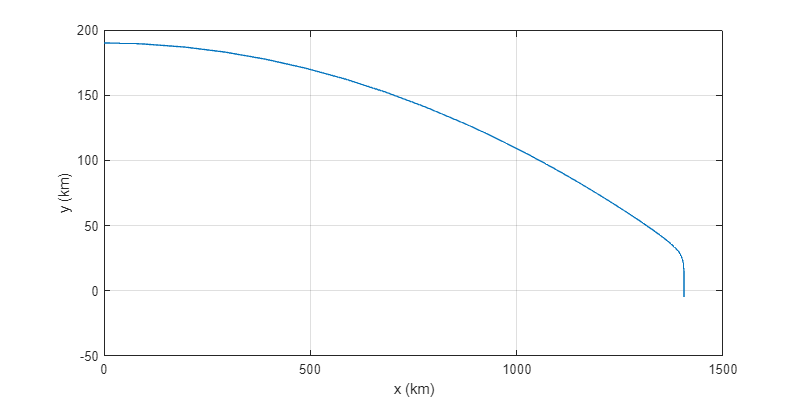

rho0 = 1.28e9;
H = 9;
y0 = 190;
gamma = 0;
v0 = po.v;  % assume parking orbit velocity as initial velocity
ge = 9.81e-3;
beta = (Cd*A)/(2*ms);
tspan = [0 500];
yi = [v0*cosd(gamma) v0*sind(gamma) 0 y0];
[ts, y] = ode45(@yprime, tspan, yi);
plot(y(:, 3), y(:, 4))
xlabel('x (km)')
ylabel('y (km)')
grid

T.splashdown = ts(148) / (60*60)

T = struct with fields:
       hohmann: 0.719841921782681
           sys: 3
    sys_to_tli: 0.678734499956997
           tli: 60.672485358189185
      perilune: 11.303069485656463
    translunar: 1.439511096876913e+02
    splashdown: 0.115585012672365


## Mission Parameters

T.total = T.hohmann + T.sys + T.sys_to_tli + T.translunar + T.splashdown;
total = T.total / 24;
T.begin = caldays(0) + hours(0.0);
T.launch = time(T.begin);
T.parking = time(T.begin + hours(T.hohmann));
T.system_check = T.parking + hours(T.sys);
T.TranslunarInjection = T.system_check + hours(T.tli);
T.Perilune = T.TranslunarInjection + hours(T.perilune);
T.EarthArrival = T.system_check + hours(T.translunar);
T.Splashdown = T.EarthArrival + hours(T.splashdown);
fields = {'hohmann', 'sys', 'sys_to_tli', 'tli', 'perilune', 'translunar', 'splashdown', 'total'};
T = rmfield(T, fields);
T

T = struct with fields:
                  begin: 0d
                 launch: 00:00:00
                parking: 00:43:11
           system_check: 03:43:11
    TranslunarInjection: 64:23:32
               Perilune: 75:41:43
           EarthArrival: 147:40:15
             Splashdown: 147:47:11


disp("Total Mission time = " + total + " days")

Total Mission time = 6.1861 days


disp("Delta V required for Translunar Injection Burn = " + dV0 + " km/s at a flight path angle of " + gamma + " degrees")

Delta V required for Translunar Injection Burn = 3.1674 km/s at a flight path angle of 0 degrees


disp("Alititude of Perilune Approach = " + m.z + " km")

Alititude of Perilune Approach = 19643.3533 km


function  yp = yprime(ts,y)
global beta rho0 H ge
rho = rho0*exp(-y(4)/H);
v = sqrt(y(1)^2 + y(2)^2);
yp = [-beta*rho*v*y(1);
      -beta*rho*v*y(2) - ge;
      y(1);
      y(2)];
end